clc
goal=@Fun;
A=[3,2,0,0;
   0,0,3,2;
   -1,0,-1,0;
   0,-1,0,-1];
B=[120;48;-30;-30];
[x,fval]=gamultiobj(goal,4,A,B,[],[],[0,0,0,0],[120,120,120,120]);

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


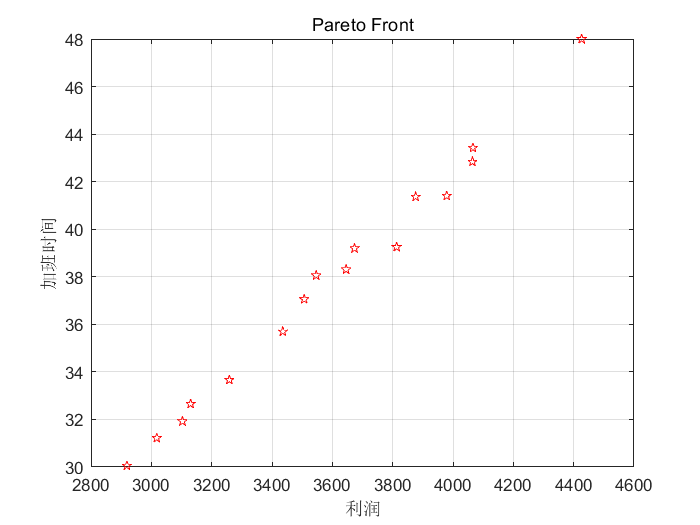

fval(:,1)=-fval(:,1);
plot(fval(:,1),fval(:,2),'pr');
xlabel('利润')
ylabel('加班时间')
title('Pareto Front')
grid on